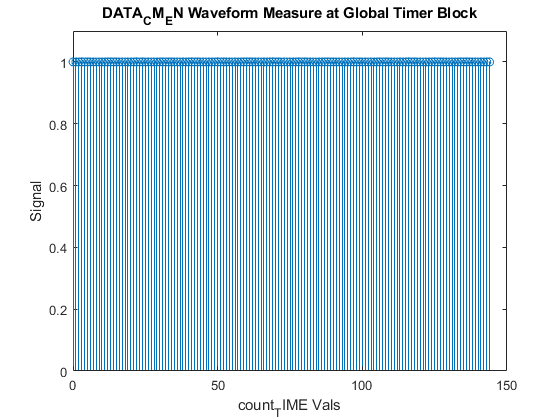

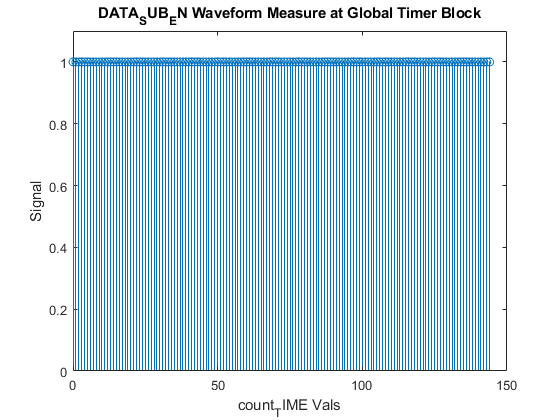

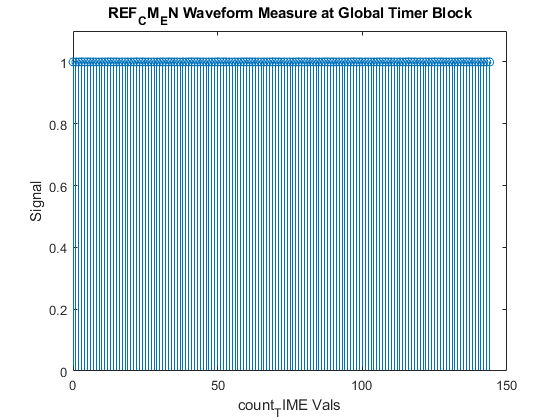

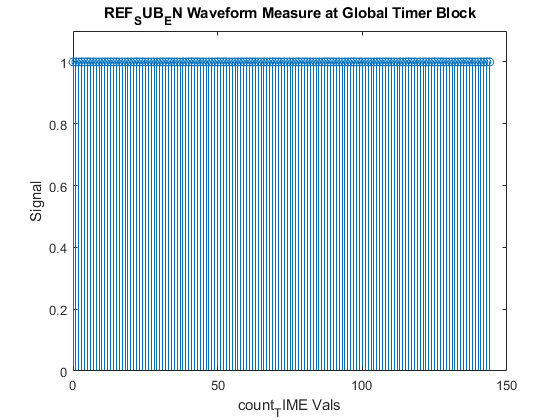

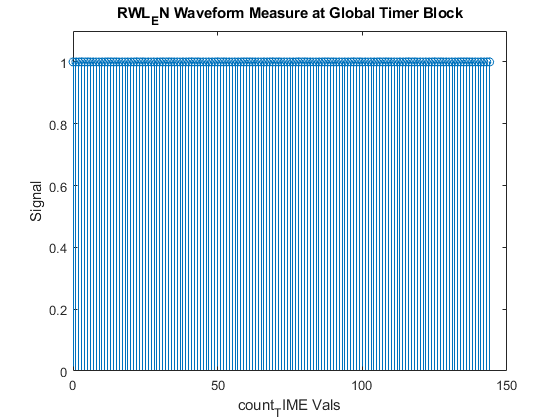

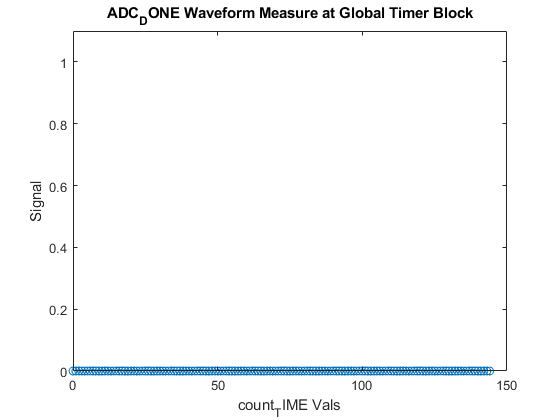

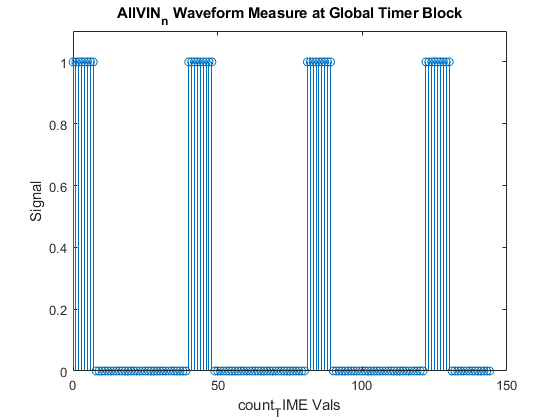

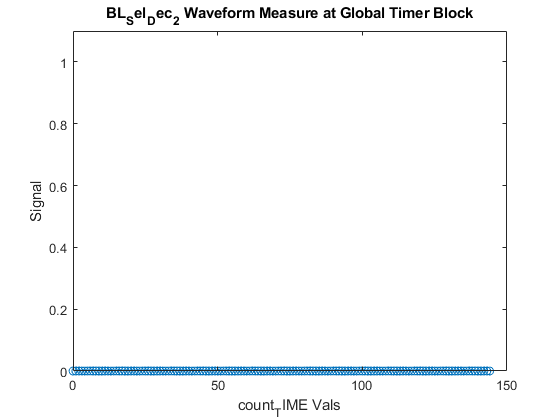

DATA_CM_EN = 1;
DATA_SUB_EN = 2;
REF_CM_EN = 3;
REF_SUB_EN = 4;
RWL_EN = 5;
ADC_DONE = 6;
AllVIN_n = 7;
BL_Sel_Dec_2 = 8;
BL_Sel_Dec_1 = 9;
BL_Sel_Dec_0 = 10;
CLK_DFF = 11;
CLK_SARLOGIC_IN = 12;
PRE_VCM = 13;
Reset_SARLOGIC = 14;
SA_EN = 15;
count_TIME_0 = 16;
count_TIME_1 = 17;
count_TIME_2 = 18;
count_TIME_3 = 19;
count_TIME_4 = 20;
count_TIME_5 = 21;
count_TIME_6 = 22;
count_TIME_7 = 23;
count_TIME_8 = 24;
count_TIME_9 = 25;
count_TIME_10 = 26;
sigNames=[
    "DATA_CM_EN";
"DATA_SUB_EN";
"REF_CM_EN";
"REF_SUB_EN";
"RWL_EN";
"ADC_DONE";
"AllVIN_n";
"BL_Sel_Dec_2";
"BL_Sel_Dec_1";
"BL_Sel_Dec_0";
"CLK_DFF";
"CLK_SARLOGIC_IN";
"PRE_VCM";
"Reset_SARLOGIC";
"SA_EN";
"count_TIME_0";
"count_TIME_1";
"count_TIME_2";
"count_TIME_3";
"count_TIME_4";
"count_TIME_5";
"count_TIME_6";
"count_TIME_7";
"count_TIME_8";
"count_TIME_9";
"count_TIME_10";
    ];
load('SARTIMING_OUT_SC_collect.mat');
for i=[1:26]
    CT = SARTIMING_OUT_SC_collect(:,16:26);
    fig=figure();
    stem([0:144],SARTIMING_OUT_SC_collect(:,i));
    title(sprintf('%s Waveform Measure at Global Timer Block',sigNames(i)));
    ylim([0 1.1]);
    xlabel('count_TIME Vals');
    ylabel('Signal');
    saveas(fig,sprintf('./plotted_signals/%s',sigNames(i)),'jpg');
    %close();
    
end